# Cvičení 9 - B2M31AEDA

## Nahrání dat

**Popis dat:** Pracovní data jsou uložena v souboru data.csv, který je k dispozici ke stažení na Moodle stránce tohoto předmětu, ve složce příslušného cvičení. Pro načtení dat do Matlabu využijte funkce `readtable`*.*

T = readtable('data.csv','ReadVariableNames',true);

## 1. Vizualizace 

% Váš kód pro scatter vizualizaci, popř. boxploty:
function ax = plotGroups(x, y, groups)
    labels = unique(groups);

    for i=1:length(labels)
        scatter(x(groups==labels(i)), y(groups==labels(i)))
        hold on
    end
    hold off

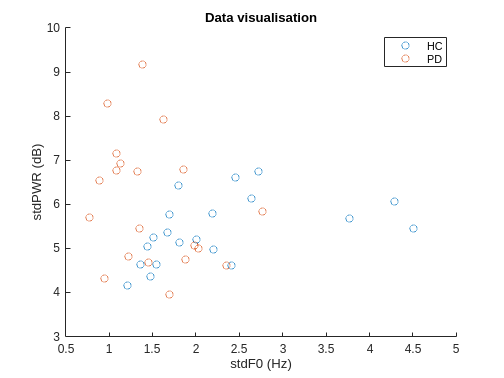


    ax = gca;
end


labels = unique(T.group);
groups = zeros(size(T.group));

for i=1:length(labels)
    groups(T.group == string(labels(i))) = i - 1;
end

ax = plotGroups(T{:, "stdF0"}, T{:, "stdPWR"}, groups);
legend(ax, labels)
xlabel("stdF0 (Hz)"); ylabel("stdPWR (dB)")
title("Data visualisation")

### **Otázky:**

- Pohledem na vaší vizualizaci zhodnoťte, jak dobře lze oddělit skupiny v 2D prostoru pomocí lineární rozhodovací hranice. Do vizualizace můžete zakreslit (od ruky) kam byste rozhodovací hranici umístili.

- Zhodnoťte, zda není pro klasifikaci některý z parametrů nadbytečný, a zvažte, jak by se obecně daly nadbytečné (redundantní) parametry automaticky identifikovat ve vícedimenzionálních datasetech.

### **Odpovědi:**

- Nelze

- Není, u obou jsou data "smíchána" a nelze je jednoduše rozdělit.

## 2. Klasifikace dat

Proveďte klasifikaci dat pomocí následujících metod a pro každou z nich vykreslete do obrázku s daty příslušnou rozhodovací hranici (decision boundary), abyste je mohli mezi sebou snadno vizuálně porovnat:

**1. Logistická regrese (Logistic regression)**

- Použijte funkce `glmfit` a `glmval`, se standardním nastavením pro binomiální rozdělení výstupní funkce.

- Pro vykreslení rozhodovací hranice můžete použít funkci `contour` na úrovni 0.5.

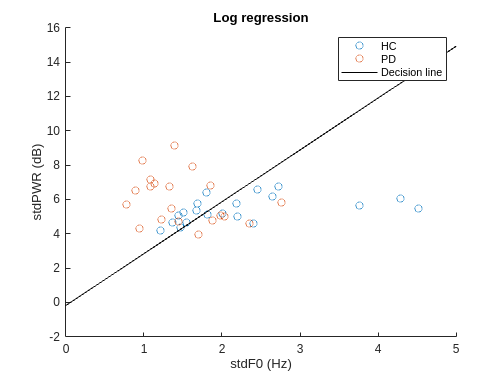

% Váš kód pro klasifikaci dat (Logistic regression)
% help glmfit
% help glmval
% help contour
X = [T.stdF0, T.stdPWR];
tic
model = glmfit(X, groups, "binomial", "Link","logit");
pLR = glmval(model,X,'logit');
LLR = double(pLR>0.5);
tLR = toc;

plotGroups(X(:,1), X(:,2),groups);
x = linspace(0,5,2);
y = (-x*model(2)+model(1))/model(3);
hold on
plot(x,y, 'black')
hold off
legend([labels; "Decision line"])

xlabel("stdF0 (Hz)"); ylabel("stdPWR (dB)")
title("Log regression")

**2. Lineární diskriminantní analýza (LDA)**

- Pro výpočet modelu použijte funkci `fitdiscr`.

- Klasifikaci původních dat můžete provést použitím funkce `predict`.

- Rozhodovací hranici vykreslete za použití koeficientů z vypočteného modelu.

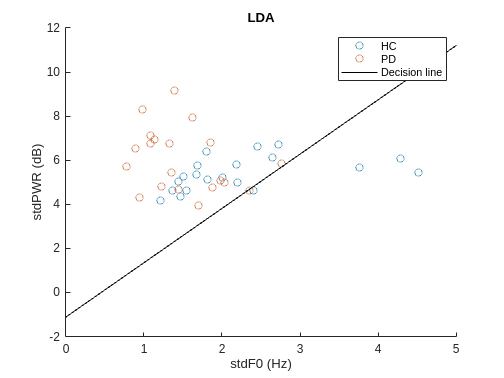

% Váš kód pro klasifikaci dat (LDA):
% help fitdiscr
% help predict
tic
model = fitcdiscr(X,groups,"DiscrimType","linear");
C = model.Coeffs(1,2);
b = [C.Const; C.Linear];
LLDA = predict(model, X);
tLDA = toc;

plotGroups(X(:,1), X(:,2),groups);
x = linspace(0,5,2);
y = (-x*b(2)+b(1))/b(3);
hold on
plot(x,y, 'black')
hold off
legend([labels; "Decision line"])
xlabel("stdF0 (Hz)"); ylabel("stdPWR (dB)")
title("LDA")

**3. Support Vector Machine **([SVM](https://en.wikipedia.org/wiki/Support_vector_machine)) s lineárním jádrem

- Výpočet SVM modelu proveďte pomocí funkce `fitcsvm`.

- Data před výpočtem SVM standardizujte! Lze standardizovat i přímo ve funkci `fitcsvm`, nicméně pokud budete kreslit rozhodovací hranice do od všech klasifikátoru do jednoho obrázku, budete muset standardizovat data ručně (abyste mohli poté de-standardizovat rozhodovací hranici).

- Vykreslete vhodným způsobem, jaké datové body určil SVM model jako *Support Vectors*.

- Koeficienty pro vykreslení rozhodovací hranice SVM modelu získáte z Matlabovské proměnné (*structure*) modelu (pole `Beta` a `Bias`).

- Klasifikaci pomocí modelu lze provést pomocí funkce `predict`, což využijete pro vyhodnocení přesnosti modelu na trénovacích datech.

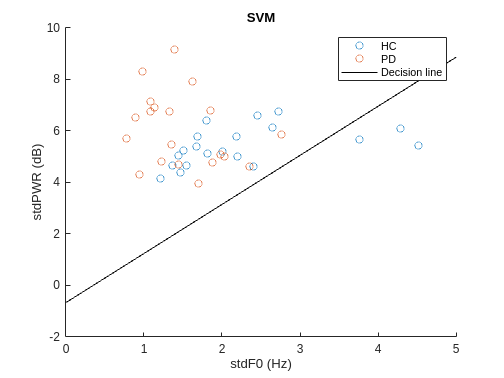

% Váš kód pro klasifikaci dat (SVM):
% help fitcsvm
tic
Xz = zscore(X);
model = fitcsvm(Xz,groups);
b = [model.Bias; model.Beta];
LSVM = predict(model, Xz);
tSVM = toc;

plotGroups(X(:,1), X(:,2),groups);
x = linspace(0,5,2);
y = (-x*b(2)+b(1))/b(3);
hold on
plot(x,y, 'black')
hold off
legend([labels; "Decision line"])
xlabel("stdF0 (Hz)"); ylabel("stdPWR (dB)")
title("SVM")

## 3. Porovnání klasifikací

Porovnejte jednotlivé klasifikátory z hlediska výpočetní náročnosti a přesnosti klasifikace.

- Pro měření výpočetní náročnosti využijte časoměrné funkce `tic` a `toc`.

- Pro každý z klasifikátorů vypočtěte a zobrazte matici záměn (*Confusion** matrix*) – využijte funkcí `confusionmat`, resp. `confusionchart`. Přesnost klasifikace určete jako procento dat, které by model přiřadil do správné skupiny.

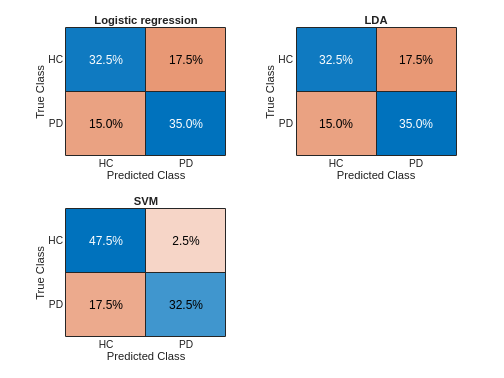

% Váš kód pro porovnání klasifikátorů
% help confusionmat
% help confusionchart

cLR = confusionmat(groups, LLR);
cLDA = confusionmat(groups, LLDA);
cSVM = confusionmat(groups, LSVM);

tiledlayout('flow');
nexttile
confusionchart(cLR,labels,'Title','Logistic regression','Normalization','total-normalized')

nexttile
confusionchart(cLDA,labels,'Title','LDA','Normalization','total-normalized')

nexttile
confusionchart(cSVM,labels,'Title','SVM','Normalization','total-normalized')

### **Délky výpočtů a procentuální přesnost klasifikace (pro všechny modely):**

Tres = table([tLR;(cLR(1,1) + cLR(2,2))/sum(cLR, "all")*100], ...
    [tLDA;(cLDA(1,1) + cLDA(2,2))/sum(cLDA, "all")*100], ...
    [tSVM;(cSVM(1,1) + cSVM(2,2))/sum(cSVM, "all")*100], ...
    'VariableNames',["Logistic regression", "LDA", "SVM"], ...
    'RowNames',["Délka výpočtu (s)", "Přesnost klasifikace (%)"]);

disp(Tres)

                                Logistic regression      LDA        SVM  
                                ___________________    _______    _______

    Délka výpočtu (s)                 0.44451          0.60694    0.45289
    Přesnost klasifikace (%)             67.5             67.5         80



### **Zhodnocení a porovnání modelů:**

LDA s Logistickou regresí mají stejné procento úspěšnosti, logistická regrese je přitom rychlejsí na výpočet. SVM je nejpomalejší metodou, ale má nejvyšší přesnost (o 12.5%)

## Nepovinný bonus:

Implementujte manuálně algoritmus pro výpočet lineární diskriminační analýzy LDA. Pro otestování funkce použijte data uložená v souboru bonus.csv, který je dostupný ke stažení na Moodlu (proměnné jsou značeny x a y).

Odevzdejte včetně grafického zobrazení dat a rozhodovací hranice.

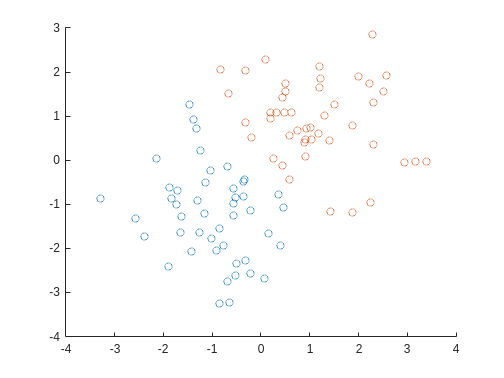

% Váš kód pro bonus:
clear all

data = readtable("bonus.csv");
X = [data.x, data.y];
Y = data.group;

labels = unique(Y);

Sw = zeros(2,2);
Sb = zeros(2,2);

mX = mean(X);

for i=1:length(labels)
    Xi = X(Y==labels(i), :);
    mXi = mean(Xi);

    Si = (Xi - mXi)' * (Xi - mXi);
    Sw = Sw + Si;

    Si = length(Xi) * (mXi - mX)' * (mXi - mX);
    Sb = Sb + Si;
end
A = Sw\Sb;
[V, D] = eig(A);

W = V(:, 1:length(labels) - 1);

XLDA = X * W * W';

plotGroups(X(:,1), X(:,2), Y);

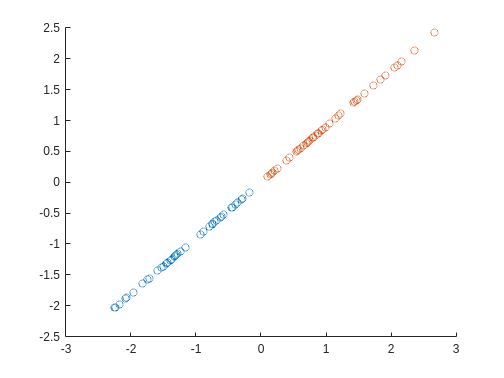

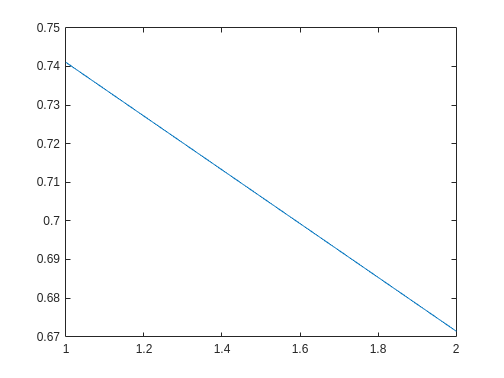

plotGroups(XLDA(:,1), XLDA(:,2), Y);